# Rocket State Estimator

Authors: Daniel J. Pearson & Colette Scott

Version: 11/22/2023

clear variables; close all; clc;

### Initialization

% State Vector
%% Initialize and assume vertical
x = [1; 0; 0; 0; 0; 0; 0; 0; 0; 0];
x_min = [1; 0; 0; 0; 0; 0; 0; 0; 0; 0];

P = eye(10); % Covariance Matrix
P_min = eye(10);

% Sensor Variance
gyroVariance = 0.00489/sqrt(40); % [Rad/s]
accelVariance = 0.00069/sqrt(40); % [m/s/s]
magVariance = 0.008; % [nT]

% Sensor Noise Covariance
R = diag([accelVariance^2,accelVariance^2,accelVariance^2,magVariance^2,magVariance^2,magVariance^2]);

gyroAccelVar = diag([gyroVariance^2, gyroVariance^2, gyroVariance^2, accelVariance^2, accelVariance^2, accelVariance^2]);

dt = 1/40; % [s]

### Rocket & Global Constants

% Global Constants
rho = 1.22; % [kg/m^3] Air Density
g = 9.81; % [m/s/s] Gravitational Acceleration 
% Rocket Constants
S_r = (pi/4)*0.152^2; % [m^2] Rocket Cross Section
C_d = 0.4; % [] Guesstimated Value of Rocket CD
m = 27.21; % [kg]

### Magnetometer Calibration

softIronCal = [
    3.5838, 0.8795, -1.1902;
    0.8795, 0.7596, -0.7211;
    -1.1902, -0.7211, 1.2511    
];

hardIronCal = [1.3071^2; 1.3130^2; 1.3042^2];

### Data Loading

% csvLog = readtable('Polaris_QuadTest_Log 2 (11-1-2023).csv');
csvLog = readtable('./polarisData.csv');

### Setup Live Plot

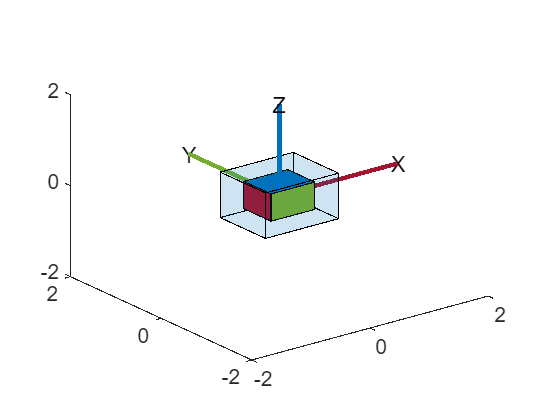

% figure;
% subplot(3,1,1);
% accelPlot = plot(NaN, NaN);
% xlabel('Time');
% ylabel('m/s^2');
% title('Acceleration (Z)');
% subplot(3,1,2);
% velZPlot = plot(NaN, NaN);
% xlabel('Time');
% ylabel('m/s');
% title('Velocity (Z)');
% subplot(3,1,3);
% altPlot = plot(NaN, NaN);
% title('Altitude');
% xlabel('Time');
% ylabel('m')

figure;
ax = axes;
view(3);  % Set the view to 3D
hold on;

pp = poseplot('Parent', gca);

### Estimation Loop

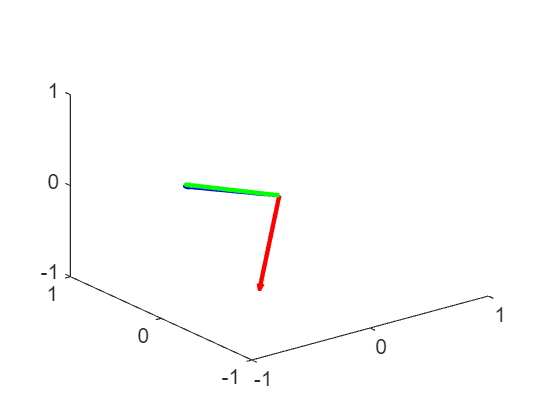

for i = 1:size(csvLog)

    accelX = csvLog.AccelX(i) * 9.81; % [m/s^2]
    accelY = csvLog.AccelY(i) * 9.81; % [m/s^2]
    accelZ = csvLog.AccelZ(i) * 9.81; % [m/s^2]

    gyroX = csvLog.GyroX(i) * (pi/180); % [rad/s]
    gyroY = csvLog.GyroY(i) * (pi/180); % [rad/s]
    gyroZ = csvLog.GyroZ(i) * (pi/180); % [rad/s]

    magX = csvLog.MagX(i) * 100; % [μT]
    magY = csvLog.MagY(i) * 100; % [μT]
    magZ = (-1)*csvLog.MagZ(i) * 100; % [μT]

    u = [gyroX; gyroY; gyroZ; accelX; accelY; accelZ];

    x_min = measurementFunction(x,u,dt);

    A = measurementJacobian(u, dt);

    W = gyroNoisePropagation(x,dt);

    Q = W * gyroAccelVar * W';

    P_min = A*P*A' + Q;

    % Apply Magnetometer Calibration Factor and Normalize
    magVector = softIronCal * ([magX;magY;magZ] - hardIronCal);
    magVector = magVector / norm(magVector);

    % Normalize Acceleration
    accelVector = [accelX; accelY; accelZ];
    accelVector = accelVector / norm(accelVector);

    % Sensor Observation Matrix
    z = [accelVector; magVector];

    h = updateFunction(x_min);
    H = updateJacobian(x_min);

    v = z - h;
    S = H*P_min*H' + R;
    K = P_min*H' / S;
    
    x = x_min + K*v;
    
    P = (eye(10) - K*H)*P_min;

    axesRot = quat2rotm(x(1:4)');
    x_axis = axesRot(:, 1);
    y_axis = axesRot(:, 2);
    z_axis = axesRot(:, 3);
    origin = [0 0 0];

    % Define the length of the axes
    axis_length = 1.0;

    cla(ax);

    % Plot the axes using quiver3
    quiver3(origin(1), origin(2), origin(3), x_axis(1)*axis_length, x_axis(2)*axis_length, x_axis(3)*axis_length, 'r', 'LineWidth', 2);
    quiver3(origin(1), origin(2), origin(3), y_axis(1)*axis_length, y_axis(2)*axis_length, y_axis(3)*axis_length, 'g', 'LineWidth', 2);
    quiver3(origin(1), origin(2), origin(3), z_axis(1)*axis_length, z_axis(2)*axis_length, z_axis(3)*axis_length, 'b', 'LineWidth', 2);
    % Set axis limits as needed
    axis([-1 1 -1 1 -1 1]); % Adjust as needed

    drawnow;

    % pause(dt);
    % 
    % angles = quat2eul(x(1:4)');
    % 
    % currentTime = csvLog.Timestamp(i);
    % 
    % x_data = get(accelPlot, 'XData');
    % accelData = get(accelPlot, 'YData');
    % altData = get(altPlot, 'YData');
    % velZData = get(velZPlot, 'YData');
    % 
    % x_data = [x_data, currentTime];
    % accelData = [accelData, linearAccel(3)];
    % altData = [altData, x(7)];
    % velZData = [velZData, x(10)];
    % 
    % set(accelPlot, 'XData', x_data, 'YData', accelData);
    % set(altPlot, 'XData', x_data, 'YData', altData);
    % set(velZPlot, 'XData', x_data, 'YData', velZData);
    % % writematrix(x', 'dataLog.csv', 'WriteMode', 'append');
    % 
    % pause(dt);
    % % Refresh the plot
    % drawnow;
end

function f = measurementFunction(x,u,dt)
    % x = x / norm(x); % Normalize Quaternion
    quat = x(1:4);
    quat = quat / norm(quat);

    G_NED = [0;0; -9.81];

    p = u(1); q = u(2); r = u(3);
    bodyAccel = [u(3); u(4); u(5)];

    dq = [
      quat(1) - (dt/2)*p*quat(2) - (dt/2)*q*quat(3) - (dt/2)*r*quat(4);
      quat(2) + (dt/2)*p*quat(1) - (dt/2)*q*quat(4) + (dt/2)*r*quat(3);
      quat(3) + (dt/2)*p*quat(4) + (dt/2)*q*quat(1) - (dt/2)*r*quat(2);
      quat(4) - (dt/2)*p*quat(3) + (dt/2)*q*quat(2) + (dt/2)*r*quat(1);
    ];

    dq = dq / norm(dq);

    rotm = quat2rotm(quat(1:4)');
    bodyGrav = rotm' * G_NED;
    linearAccelBody = bodyAccel - bodyGrav;

    accelNED = rotm' * linearAccelBody;

    dv = [
        x(7) + accelNED(1) * dt;
        x(8) + accelNED(2) * dt;
        x(9) + accelNED(3) * dt;
    ];

    dp = [
        x(4) + accelNED(1) * (1/2)*dt^2;
        x(5) + accelNED(2) * (1/2)*dt^2;
        x(6) + accelNED(3) * (1/2)*dt^2;
    ];

    f = [dq; dv; dp];

end

function A = measurementJacobian(u,dt)

    p = u(1); q = u(2); r = u(3);

    A = [
        1, -0.5*dt*p, -0.5*dt*q, -0.5*dt*r, 0, 0, 0, 0, 0, 0;
        0.5*dt*p, 1, 0.5*dt*r, -0.5*dt*q, 0, 0, 0, 0, 0, 0;
        0.5*dt*q, -0.5*dt*r, 1, 0.5*dt*p, 0, 0, 0, 0, 0, 0;
        0.5*dt*r, 0.5*dt*q, -0.5*dt*p, 1, 0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, dt, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, dt, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0, (1/2)*dt^2, 0, 0, 0;
        0, 0, 0, 0, 0, 0, 0, (1/2)*dt^2, 0, 0;
        0, 0, 0, 0, 0, 0, 0, 0, (1/2)*dt^2, 0;
        0, 0, 0, 0, 0, 0, 0, 0, 0, (1/2)*dt^2;
    ];
    
end

function h = updateFunction(x)

    r = [20468; -4540.5; 46559.4];
    r = r / norm(r);

    G = [0; 0; -9.81];
    G = G / norm(G);

    q = x(1:4);
    q = q / norm(q);

    rotm = quat2rotm(q');
    
    a_hat = rotm*G;
    m_hat = rotm*r;

    h = [
        a_hat; 
        m_hat;
    ];
end

function H = updateJacobian(x)
    r = [20468; -4540.5; 46559.4];
    r = r / norm(r);

    G = [0; 0; -9.81];
    G = G / norm(G);

    q = x(1:4);
    q = q / norm(q);
    
    rx = r(1);
    ry = r(2);
    rz = r(3);
    gx = G(1);
    gy = G(2);
    gz = G(3);
    
    qw = q(1);
    qx = q(2);
    qy = q(3);
    qz = q(4);
    
    H = [
        gx*qw+gy*qz-gz*qy, gx*qx+gy*qy+gz*qz, -gx*qy+gy*qx-gz*qw, -gx*qz+gy*qw+gz*qx, 0, 0, 0, 0, 0, 0;
        -gx*qz+gy*qw+gz*qx, gx*qy-gy*qx+gz*qw, gx*qx+gy*qy+gz*qz, -gx*qw-gy*qz+gz*qy, 0, 0, 0, 0, 0, 0;
        gx*qy-gy*qx+gz*qw, gx*qz-gy*qw-gz*qx, gx*qw+gy*qz-gz*qy, gx*qx+gy*qy+gz*qz, 0, 0, 0, 0, 0, 0;
        rx*qw+ry*qz-rz*qy, rx*qy+ry*qy+rz*qz, -rx*qy+ry*qx-rz*qw, -rx*qz+ry*qw+rz*qx, 0, 0, 0, 0, 0, 0;
        -rx*qz+ry*qw+rz*qx, rx*qy-ry*qx+rz*qw, rx*qx+ry*qy+rz*qz, -rx*qw-ry*qz+rz*qy, 0, 0, 0, 0, 0, 0;
        rx*qy-ry*qx+rz*qw, rx*qz-ry*qw-rz*qx, rx*qw+ry*qz-rz*qy, rx*qx+ry*qy+rz*qz, 0, 0, 0, 0, 0, 0;
    ];

end

function W = gyroNoisePropagation(x,dt)
    W = [
        -0.5*x(2), -0.5*x(3), -0.5*x(4), 0, 0, 0;
        0.5*x(1), -0.5*x(4), 0.5*x(3), 0, 0, 0;
        0.5*x(4), 0.5*x(1), -0.5*x(2), 0, 0, 0;
        -0.5*x(3), 0.5*x(2), 0.5*x(1), 0, 0, 0;
        0, 0, 0, x(5), 0, 0;
        0, 0, 0, 0, x(6), 0;
        0, 0, 0, 0, 0, x(7);
        0, 0, 0, x(5), 0, 0;
        0, 0, 0, 0, x(6), 0;
        0, 0, 0, 0, 0, x(7);
    ];
end